clear
% SNR in plots are power SNRs
% number_averages = 2000; % number of averages for waveforms (averaging
% waveforms then phase). Use either this or the below 2 lines

number_averages_phase = 2500000;  % if averaging phase directly
latched_hold_time = 1e-6; % when performing latching experiment, latched data collected and averaged for this long.
% this is then plotted in a separate histogram
number_averages = round(number_averages_phase/16); % convert back to number of waveforms to decide on length (time) of signal

number_iterations = 1; % calculate averaged phase for this many different iterations of noise.
sin_wave_amp_1 = .562e-3;   % amplitude of the clean input sin wave. not as important as the SNR.
sin_wave_amp_2 = 0.1e-3;
snr = 1;   % this is SNR of power.SNR of the white noise signal. This is only BW limited by the sampling frequency (sampling_freq/2)
% snr = .1;
% this number will be further increased by a factor of ~7 by the analog BPFs
snr = sqrt(snr)  % voltage SNR, so sd of noise can be calculated directly.

snr = 1

phase_0= 50 * pi/180;  % phase of state 0 of the clean rts signal
phase_1 = 28* pi/180 + phase_0; % phase of state 1 of the clean rts signal
if_freq = 21e6;   % frequency of the simulated clean sin wave
sampling_freq = 168e6;   % sampling frequency of the signal
average_number_latched = latched_hold_time * sampling_freq;  % number of points that get averaged into one phase 
%point before plotting as histogram
average_emission_time = 15e-6;   % average time in state 0 (Poisson distributed)
average_capture_time = 10e-6;    % average time in state 1 
pass_band_start_chebyshev = 19.25e6;  % pass band of the digital Chebyshev filter
pass_band_stop_chebyshev = 22.75e6;
pass_band_start_inbuilt = 20e6;  % pass band of the digital inbuilt filter
pass_band_stop_inbuilt = 22e6;
noise_bw = 10e6;   % BW limit the input white noise above. Limited because of the analog BPFs (SBP 21.4+) - simulating that effect.
% The SNR after this filtering stage is the true single shot SNR in our experiment
% (calculated from the noise temp)
noise_band_start = if_freq - noise_bw/2; 
noise_band_stop = if_freq + noise_bw/2;
hist_bin_width = 6;
nbins_3d_hist = 30;
moving_mean_average_time = 0.5e-6;
moving_mean_average_number = moving_mean_average_time * sampling_freq;
hist_bin_edges = -180:hist_bin_width:180;
sd_noise_white = sin_wave_amp_1/snr;  % standard deviation of the white noise calculated from the SNR and the input sin wave amp

total_time = 2/if_freq * number_averages;   % length (Time) of signal 
time = 0: 1/sampling_freq: total_time - 1/sampling_freq;  % time points in signal sampled at sampling_freq
[time_out, rts_out] = generate_rts(time, average_capture_time, average_emission_time);
phase = zeros(1,length(rts_out));
phase (rts_out == 1) = phase_1;
phase(rts_out == 0) = phase_0;
sin_wave_amp (rts_out == 1) = sin_wave_amp_1;
sin_wave_amp(rts_out == 0) = sin_wave_amp_2;
clean_sin_wave = sin_wave_amp.*sin(2*pi*if_freq*time + phase);  % clean sin wave as defined by params above. 

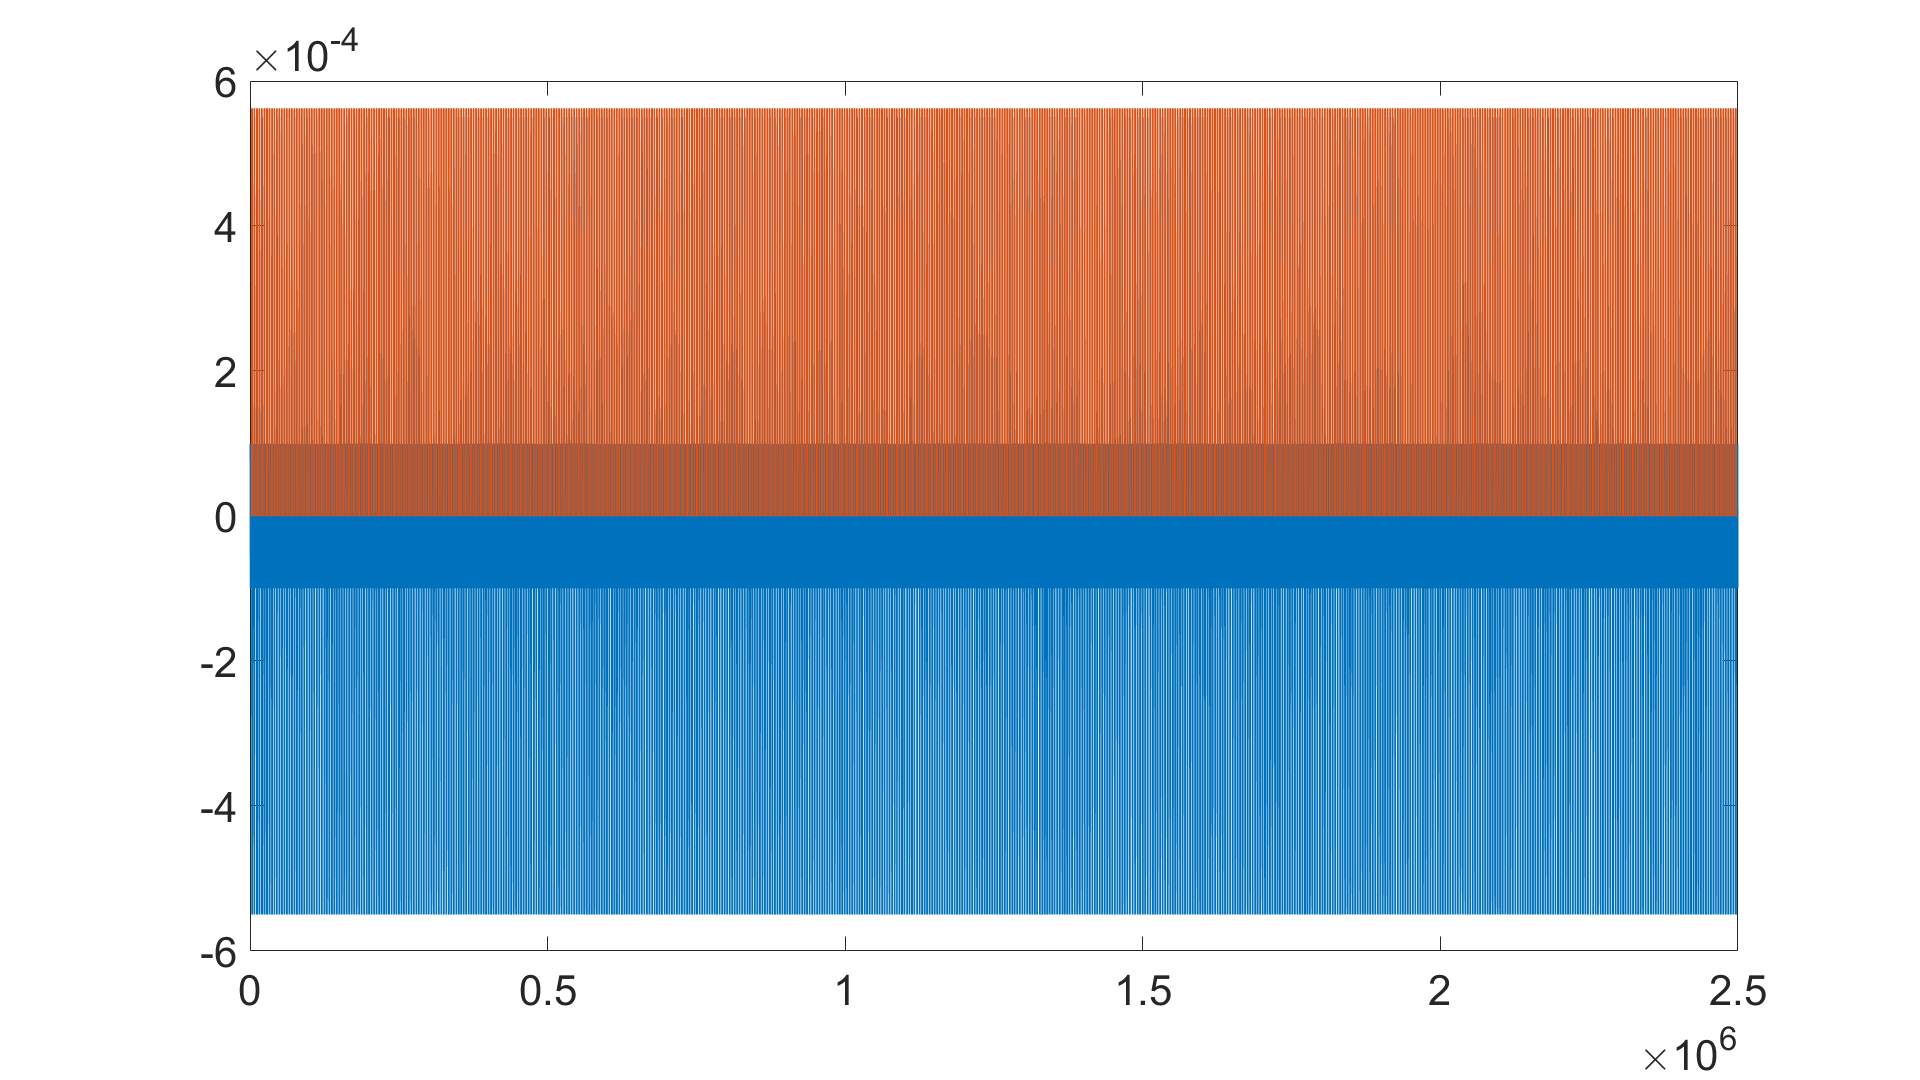

figure
plot(clean_sin_wave)
hold on
plot(rts_out *sin_wave_amp_1)
hold on

%%%%% initialize arrays
noise_white = zeros(number_iterations, length(time));
noise = noise_white;
noisy_signal = noise; 

for m_noise_iteration_number = 1 : number_iterations
    noise_white(m_noise_iteration_number,:) = sd_noise_white * randn(1,length(time));
    noise(m_noise_iteration_number,:) = bandpass(noise_white(m_noise_iteration_number,:), [noise_band_start, noise_band_stop], sampling_freq);
    noisy_signal(m_noise_iteration_number,:) = clean_sin_wave + noise(m_noise_iteration_number,:);
    [noisy_signal_amp(m_noise_iteration_number,:), noisy_signal_phase(m_noise_iteration_number,:), ...
        noisy_signal_x(m_noise_iteration_number,:), noisy_signal_p(m_noise_iteration_number,:)] = ...
        get_amp_and_phase(time,noisy_signal(m_noise_iteration_number, :), if_freq,sampling_freq);
    [clean_signal_amp(m_noise_iteration_number,:), clean_signal_phase(m_noise_iteration_number,:), ...
        clean_signal_x(m_noise_iteration_number,:), clean_signal_p(m_noise_iteration_number,:)] = ...
        get_amp_and_phase(time,clean_sin_wave(m_noise_iteration_number, :), if_freq,sampling_freq);
end
noisy_signal_phase = noisy_signal_phase * 180/pi;
for m_noise_iteration_number = 1 : number_iterations
    moving_mean_noisy_signal_phase(m_noise_iteration_number,:) = movmean(squeeze(noisy_signal_phase(m_noise_iteration_number,:)), moving_mean_average_number);
end
hist_3d_data (m_noise_iteration_number, :, 1) = noisy_signal_x(m_noise_iteration_number, :);
hist_3d_data (m_noise_iteration_number, :, 2) = noisy_signal_p(m_noise_iteration_number, :);
[hist_3d_count, hist_3d_bin_centers] = hist3(squeeze(hist_3d_data), [nbins_3d_hist, nbins_3d_hist]);
hist_3d_x_centers = [hist_3d_bin_centers{1}];
hist_3d_p_centers = [hist_3d_bin_centers{2}];

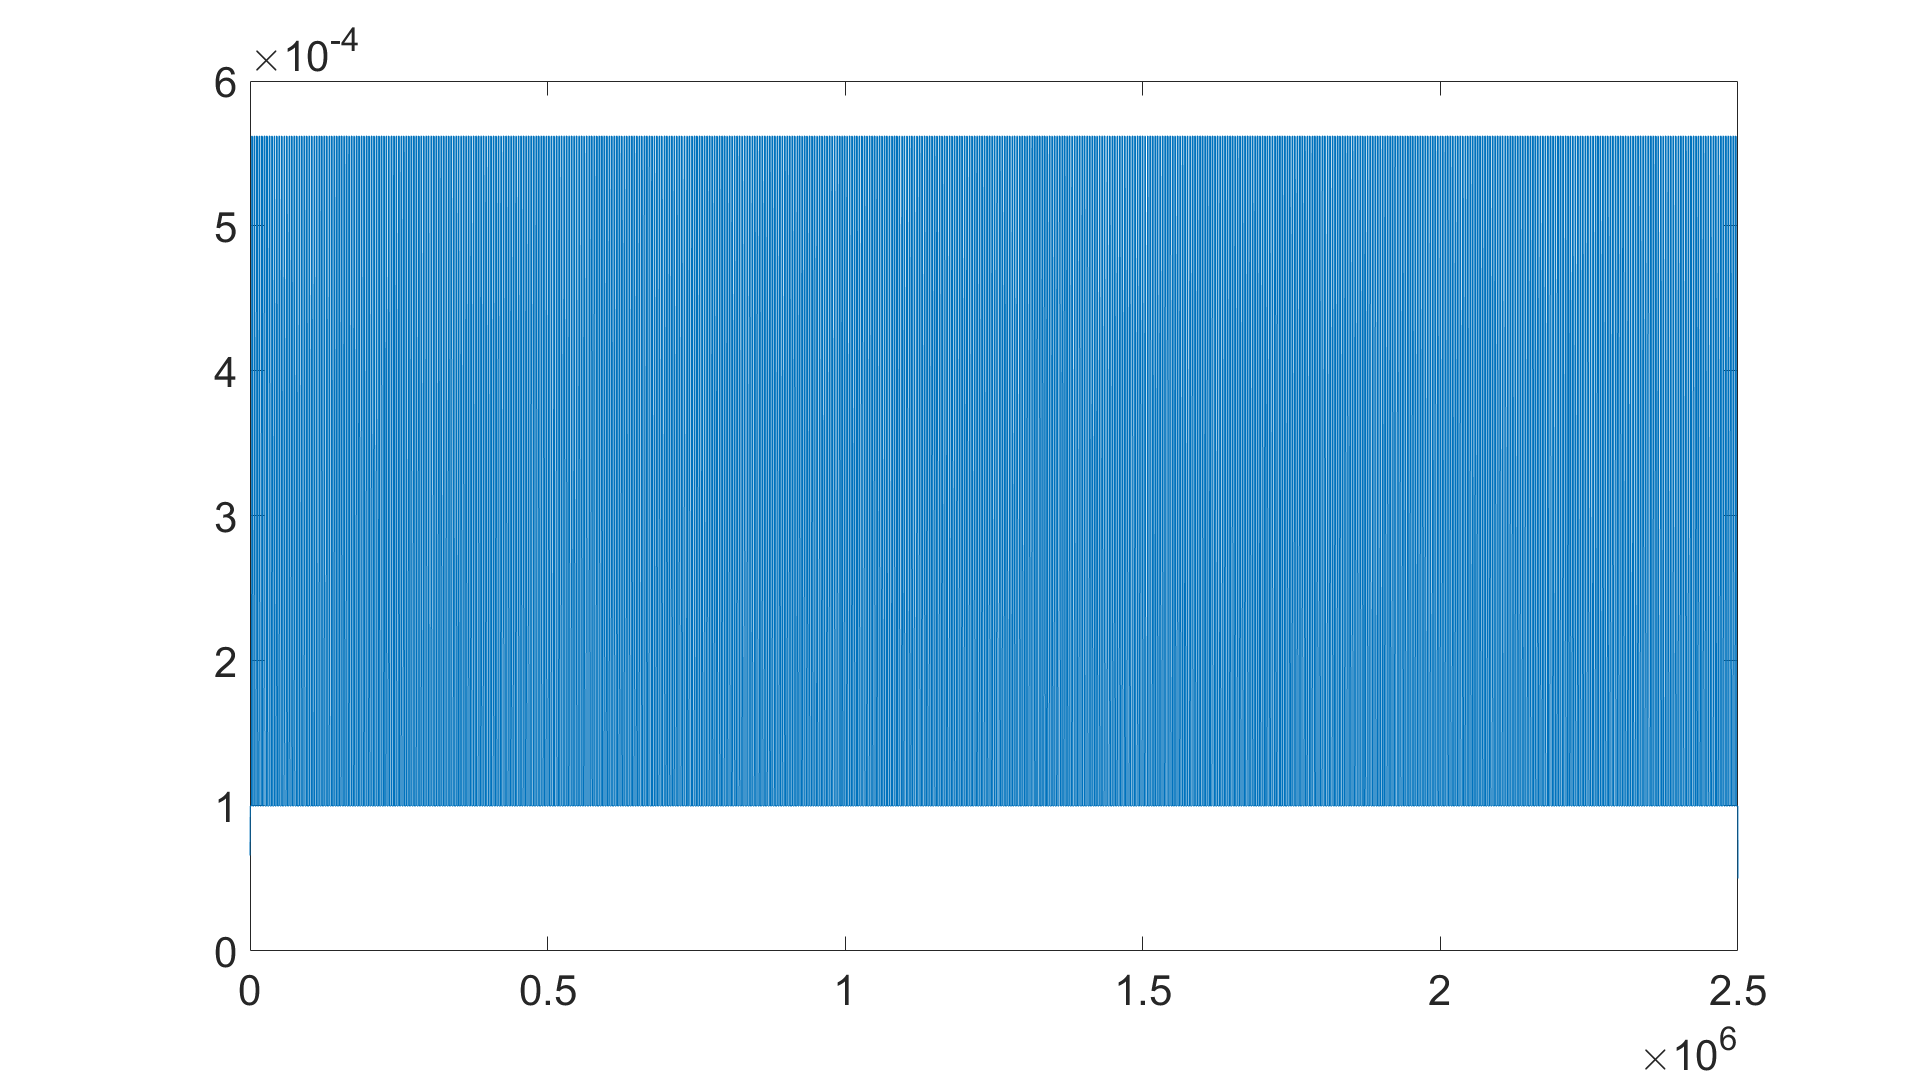

figure
plot(squeeze(clean_signal_amp(m_noise_iteration_number,:)))

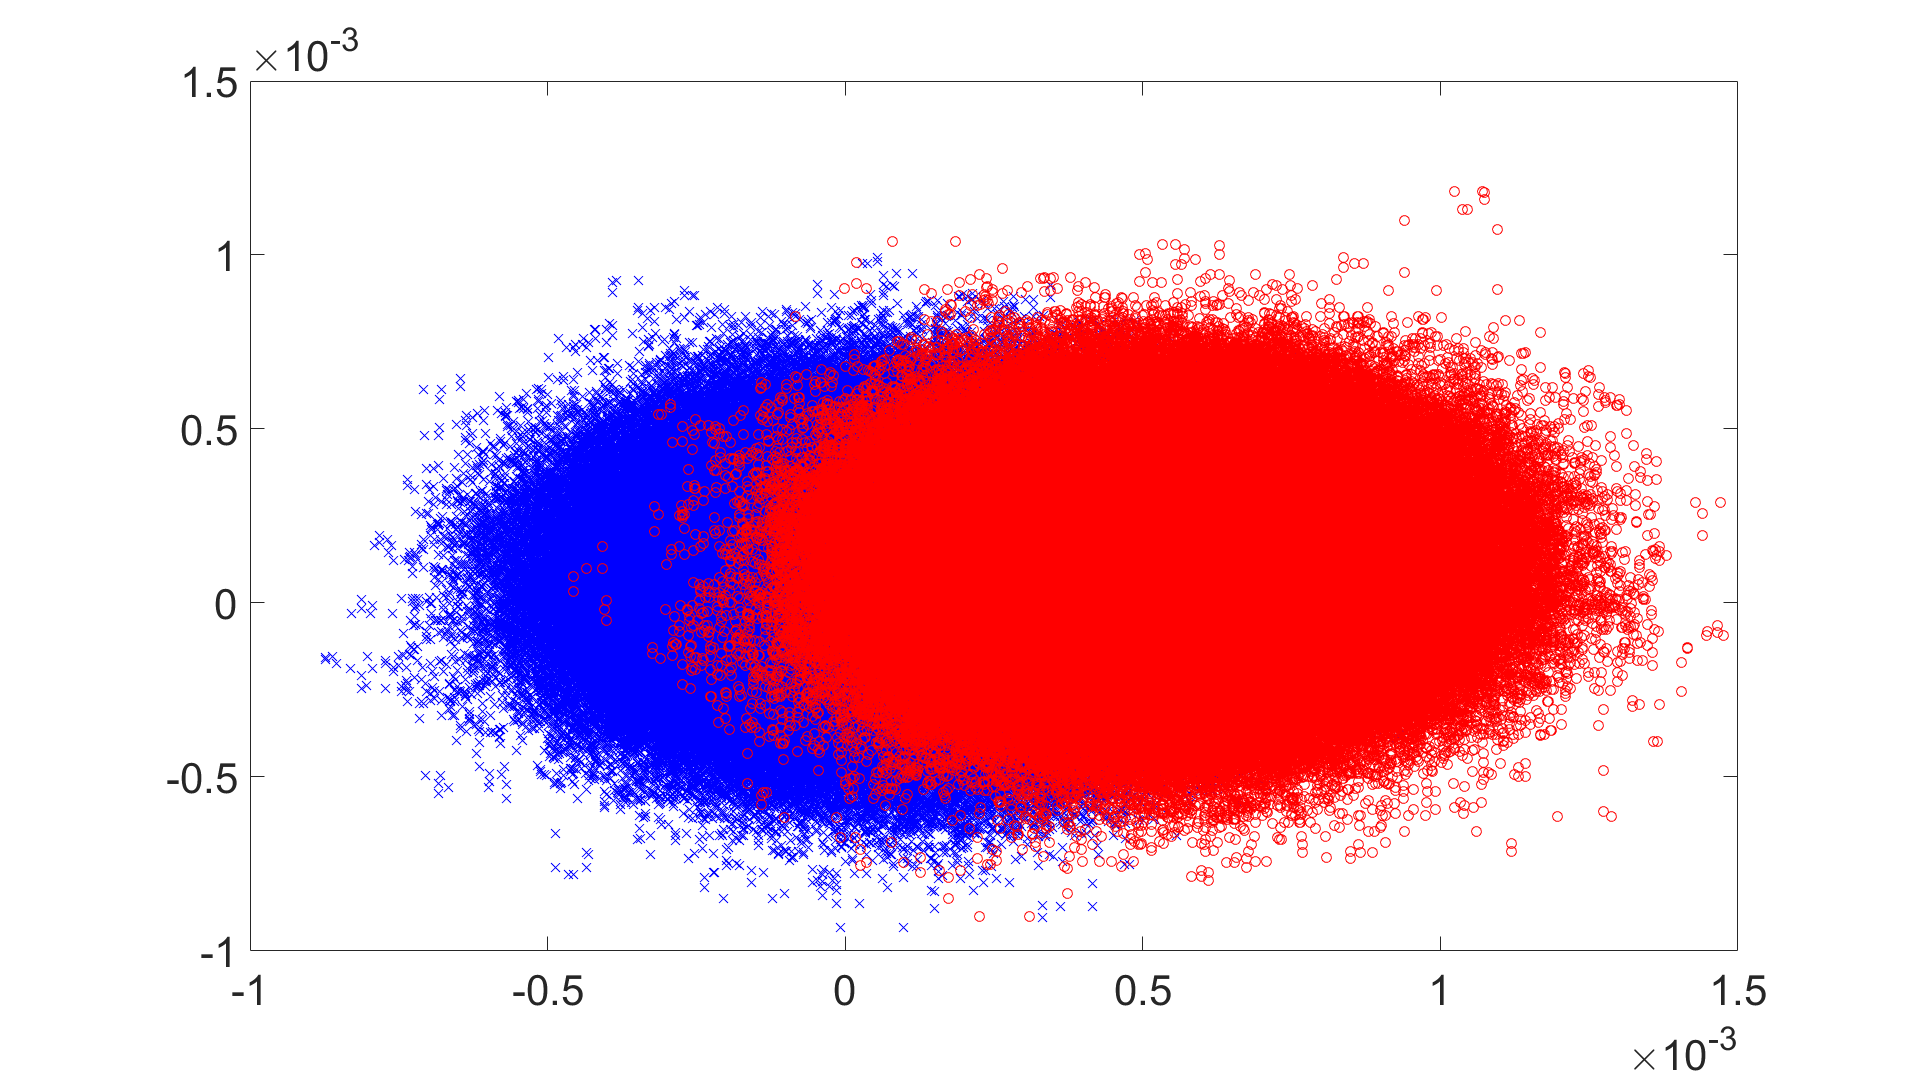

figure
plot(squeeze(noisy_signal_x(sin_wave_amp == 0.1e-3)), squeeze(noisy_signal_p(sin_wave_amp == 0.1e-3)), 'bx')
hold on
plot(squeeze(noisy_signal_x(sin_wave_amp == 0.562e-3)), squeeze(noisy_signal_p(sin_wave_amp == 0.562e-3)), 'ro')

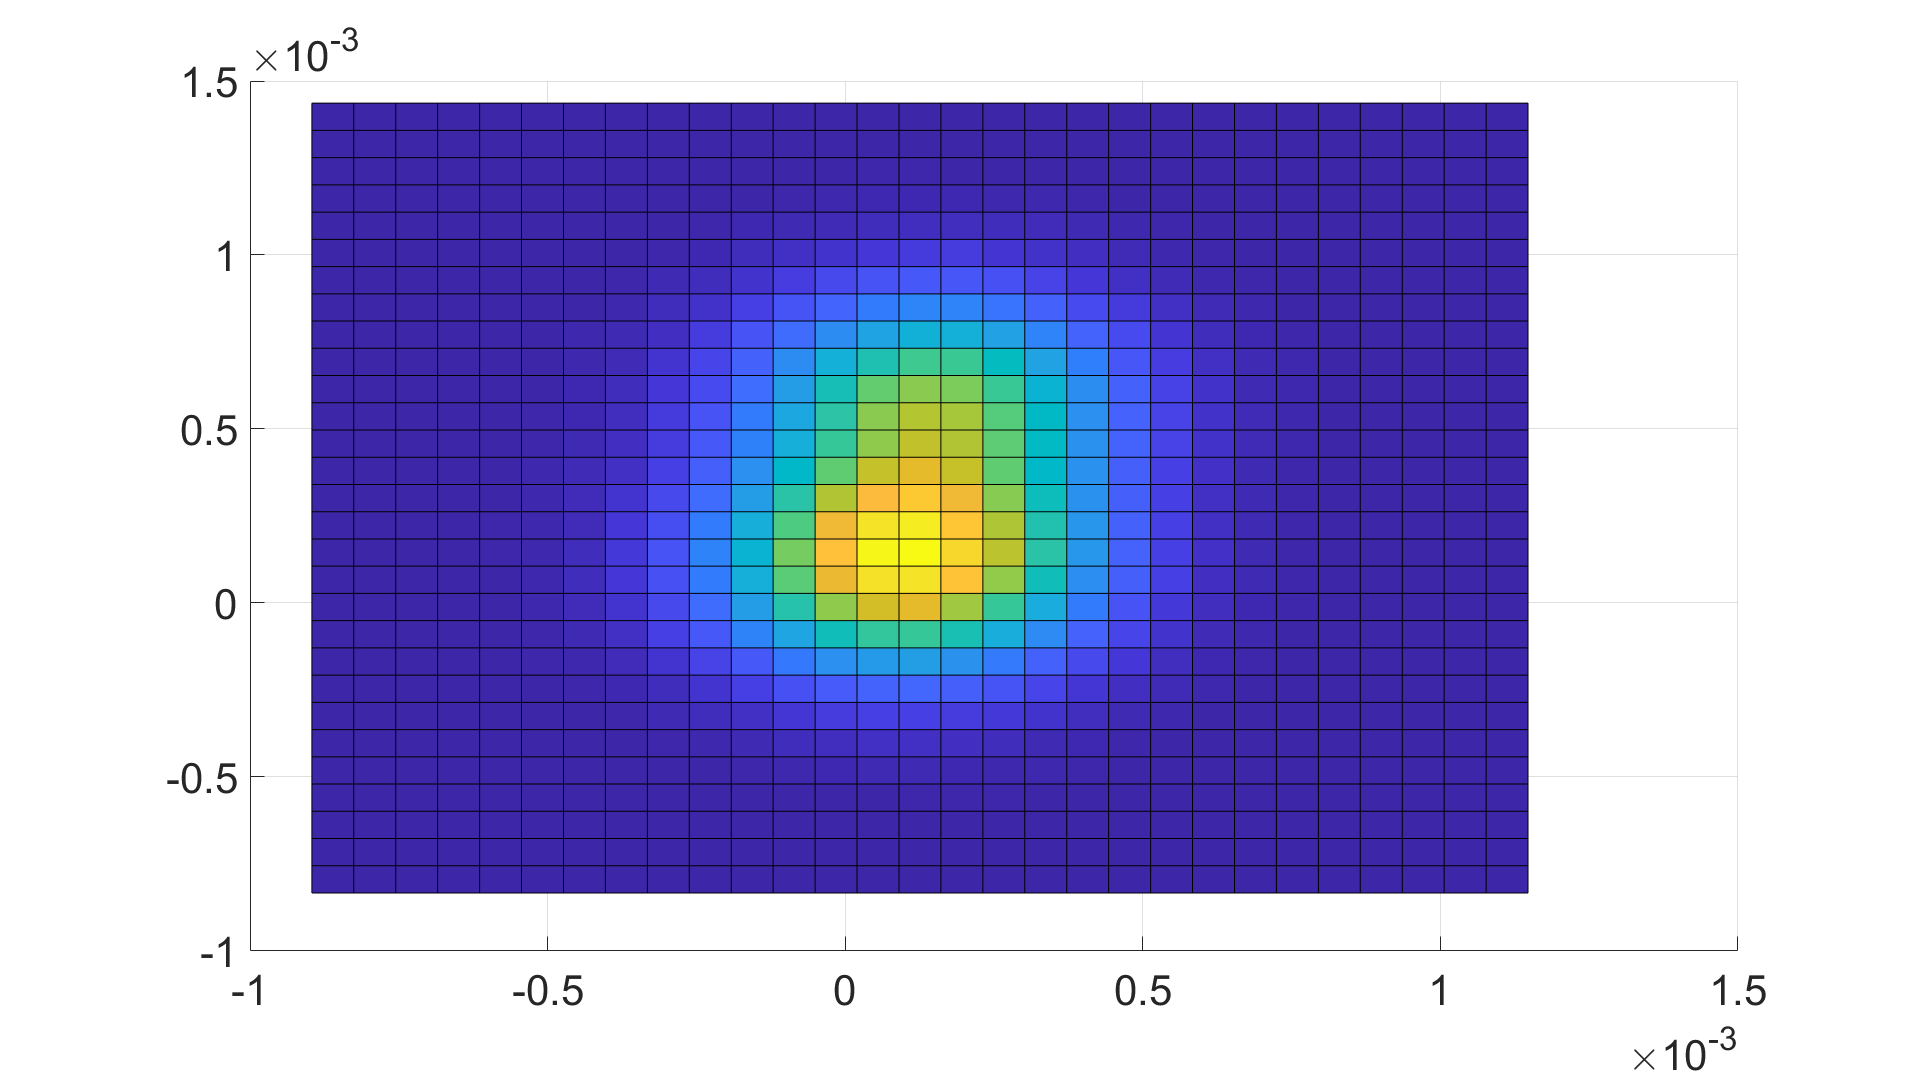

figure
surf(hist_3d_p_centers, hist_3d_x_centers, hist_3d_count)
view(0,90)

% for m_noise_iteration_number = 1 : number_iterations
%     [clean_time_data(m_noise_iteration_number,:), raw_data_out(m_noise_iteration_number,:), clean_RTS_data(m_noise_iteration_number,:), ...
%         simple_threshold_clean_RTS_data(m_noise_iteration_number,:), ...
%         gaussian_1_mean(m_noise_iteration_number), gaussian_2_mean(m_noise_iteration_number), sigma_double_gaussian(m_noise_iteration_number), ...
%         double_gaussian_fit_error(m_noise_iteration_number), area_gaussian_1(m_noise_iteration_number), area_gaussian_2(m_noise_iteration_number), ...
%     lifetime_state_1_final_iteration(m_noise_iteration_number), lifetime_state_2_final_iteration(m_noise_iteration_number), ...
%     lifetime_state_1_iteration_array(m_noise_iteration_number,:), lifetime_state_2_iteration_array(m_noise_iteration_number,:), ...
%     threshold_1_iteration_array(m_noise_iteration_number, :), threshold_2_iteration_array(m_noise_iteration_number, :), ...
%     gaussian_1_theory_values(m_noise_iteration_number, :), gaussian_2_theory_values(m_noise_iteration_number, :), hist_RTS_bins(m_noise_iteration_number,:), ...
%     hist_count_data(m_noise_iteration_number,:), single_gaussian_fit_params(m_noise_iteration_number, :), ...
%     single_gaussian_theory_values(m_noise_iteration_number,:), single_gaussian_fit_error(m_noise_iteration_number)] = ...
%     clean_noisy_RTS_signal(squeeze(time(m_noise_iteration_number,:)), squeeze(noisy_signal_phase(m_noise_iteration_number,:)), 20, 4, hist_bin_edges, 13);
% end

for m_noise_iteration_number = 1 : number_iterations
    [clean_time_data_mov_mean(m_noise_iteration_number,:), raw_data_out_mov_mean(m_noise_iteration_number,:), ...
        clean_RTS_data_mov_mean(m_noise_iteration_number,:), gaussian_1_mean_mov_mean(m_noise_iteration_number), ...
        gaussian_2_mean_mov_mean(m_noise_iteration_number), sigma_double_gaussian_mov_mean(m_noise_iteration_number), ...
        double_gaussian_fit_error_mov_mean(m_noise_iteration_number), area_gaussian_1_mov_mean(m_noise_iteration_number), ...
        area_gaussian_2_mov_mean(m_noise_iteration_number), lifetime_state_1_final_iteration_mov_mean(m_noise_iteration_number), ...
        lifetime_state_2_final_iteration_mov_mean(m_noise_iteration_number), lifetime_state_1_iteration_array_mov_mean(m_noise_iteration_number,:), ...
        lifetime_state_2_iteration_array_mov_mean(m_noise_iteration_number,:), simple_threshold_clean_RTS_data_mov_mean(m_noise_iteration_number,:), ...
        simple_threshold_lifetime_state_1(m_noise_iteration_number), simple_threshold_lifetime_state_2(m_noise_iteration_number), ...
        threshold_1_iteration_array_mov_mean(m_noise_iteration_number, :), ...
        threshold_2_iteration_array_mov_mean(m_noise_iteration_number, :), gaussian_1_theory_values_mov_mean(m_noise_iteration_number, :), ...
        gaussian_2_theory_values_mov_mean(m_noise_iteration_number, :), hist_RTS_bins_mov_mean(m_noise_iteration_number,:), ...
        hist_count_data_mov_mean(m_noise_iteration_number,:), single_gaussian_fit_params_mov_mean(m_noise_iteration_number, :), ...
        single_gaussian_theory_values_mov_mean(m_noise_iteration_number,:), single_gaussian_fit_error_mov_mean(m_noise_iteration_number)] = ...
    clean_noisy_RTS_signal(squeeze(time(m_noise_iteration_number,:)), squeeze(moving_mean_noisy_signal_phase(m_noise_iteration_number,:)), ...
    20, 5, hist_bin_edges, 13);
end

% for m_noise_iteration_number = 1 : number_iterations
%     [clean_time_data, clean_RTS_amp_data, raw_data_out,gaussian_1_mean, gaussian_2_mean, sigma_double_gaussian, double_gaussian_error, area_gaussian_1, area_gaussian_2, lifetime_state_1, lifetime_state_2, ...
%     lifetime_state_1_array, lifetime_state_2_array, threshold_1_array, threshold_2_array, theory_hist_phases, theory_gaussian_1, theory_gaussian_2, hist_axis, shifted_hist_data, single_gaussian_fit, ...
%     single_theory_gaussian, single_gaussian_fit_error] = ...
%     clean_noisy_RTS_signal_old_version(squeeze(time(m_noise_iteration_number,:)), squeeze(noisy_signal_phase(m_noise_iteration_number,:)), 4, hist_bin_edges);
% end

for m_noise_iteration_number = 1 : number_iterations
    [clean_time_data_mov_mean, clean_RTS_amp_data_mov_mean, raw_data_out_mov_mean_old,gaussian_1_mean_mov_mean, gaussian_2_mean_mov_mean, ...
        sigma_double_gaussian_mov_mean, double_gaussian_error_mov_mean, area_gaussian_1_mov_mean, area_gaussian_2_mov_mean,  ...
        lifetime_state_1_mov_mean, lifetime_state_2_mov_mean, lifetime_state_1_array_mov_mean, lifetime_state_2_array_mov_mean, ...
        threshold_1_array_mov_mean, threshold_2_array_mov_mean, theory_hist_phases_mov_mean, theory_gaussian_1_mov_mean, ...
        theory_gaussian_2_mov_mean, hist_axis_mov_mean, shifted_hist_data_mov_mean, single_gaussian_fit_mov_mean, ...
        single_theory_gaussian_mov_mean, single_gaussian_fit_error_mov_mean] = ...
    clean_noisy_RTS_signal_old_version(squeeze(time(m_noise_iteration_number,:)), squeeze(moving_mean_noisy_signal_phase(m_noise_iteration_number,:)), 20, hist_bin_edges);
end

figure
plot(time,noisy_signal_phase, 'b', 'DisplayName', 'noisy signal phase')
hold on 
plot(time, moving_mean_noisy_signal_phase, 'r', 'DisplayName', 'noisy signal mov mean')
plot(time, raw_data_out_mov_mean)
plot(time, raw_data_out_mov_mean_old)
% plot(time, clean_RTS_data, 'r', 'linewidth', 3, 'DisplayName', 'cleaned new version')
plot(time, clean_RTS_data_mov_mean(end, :), 'm', 'linewidth', 3, 'DisplayName', 'cleaned mov mean new version')
plot(time, simple_threshold_clean_RTS_data_mov_mean, 'y', 'linewidth', 3, 'DisplayName', 'simple thresholding mov mean')
plot(time, clean_RTS_amp_data_mov_mean, 'k', 'linewidth', 3, 'DisplayName', 'cleaned move mean old version')
plot(time, 180/pi*phase, 'g', 'linewidth', 3, 'DisplayName', 'input phase')

[freqs, psd, psd_dBm] = ...
    extract_PSD(time, clean_RTS_data_mov_mean);
theoretical_lorentzian = 2*(abs(gaussian_1_mean_mov_mean - gaussian_2_mean_mov_mean))^2 * (lifetime_state_1_final_iteration_mov_mean ...
    * lifetime_state_2_final_iteration_mov_mean)^2 ./(lifetime_state_1_final_iteration_mov_mean + lifetime_state_2_final_iteration_mov_mean)^3 ...
    ./ (1 + 4*pi^2 .* freqs.^2 ./ (1/lifetime_state_1_final_iteration_mov_mean + ...
    1 / lifetime_state_1_final_iteration_mov_mean )^2);

figure
plot(freqs(freqs < 1e6), psd_dBm(freqs < 1e6))
hold on
plot(freqs(freqs < 1e6), -30 + 10*log10(theoretical_lorentzian(freqs < 1e6)/1e-3))
